# Plantilla para el TAP2 - MN - 2022_2

Integrantes:

- Joaquín Francisco Jordán O'Connor

- ________________________________________________________________________

- _________________________________________________________________________

- _________________________________________________________________________

- _________________________________________________________________________

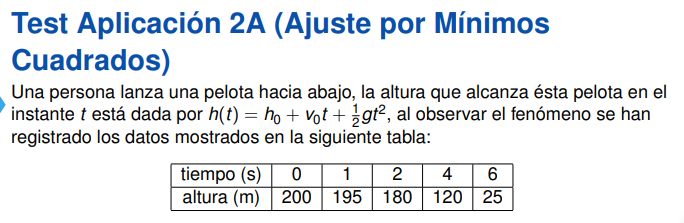

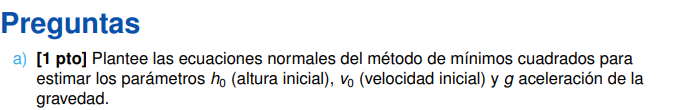

%escriba la solución aquí...




%escriba la solución aquí...



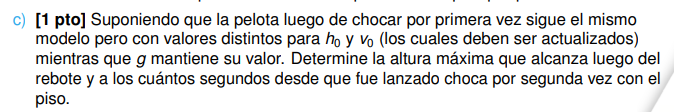

%escriba la solución aquí...



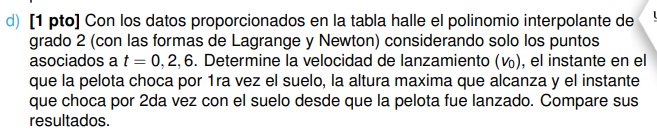

%escriba la solución aqui....


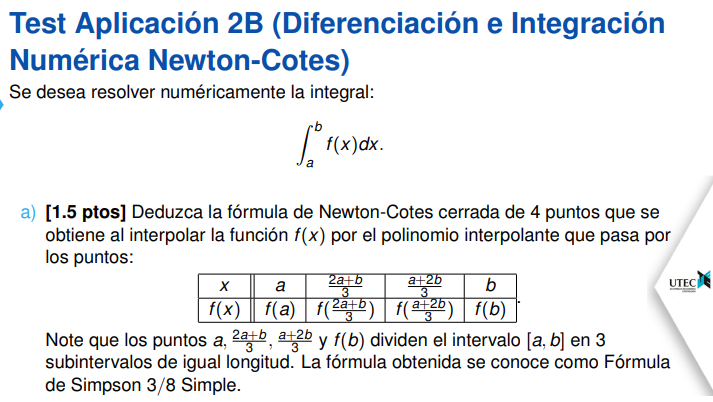

%escriba aquí la solución....

%escriba aquí la solución....

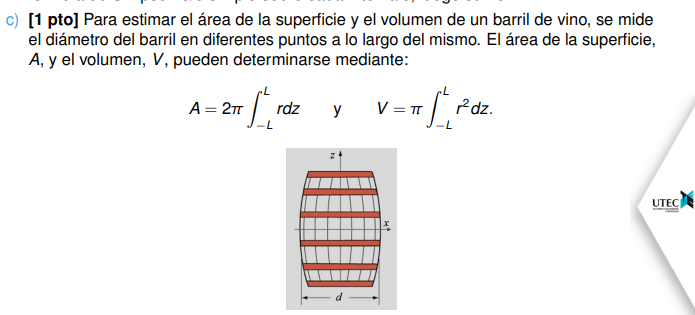

                 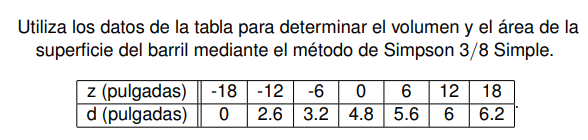

%escriba aquí la solución....

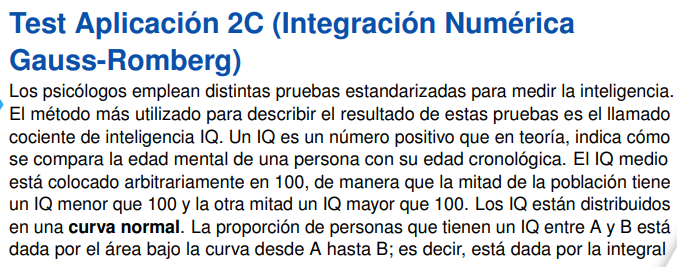

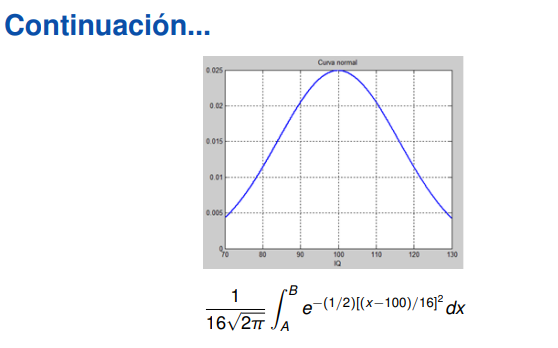

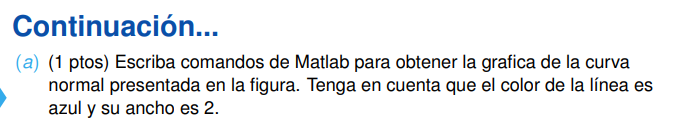

%Escriba aquí la solucion


%Escriba aquí la solucion


%Escriba aquí la solucion


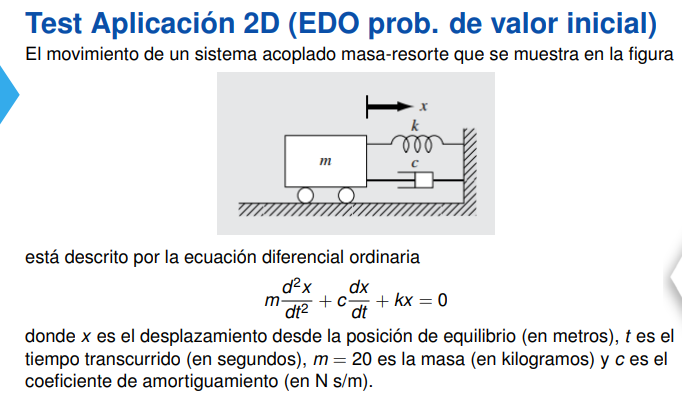

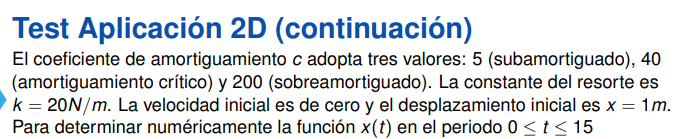

% Se realiza v = x'(t)
% Para cada valor de c los datos son
x0 = 1; %Desplazamiento inicial
v0 = 0; %Velocidad inicial
m = 20; %Masa
k = 20; %Constante del resorte
a = 0; %Inicio del periodo
b = 15; %Fin del periodo

% x' = v
% v' = -k/m*x - c/m * v;

%Para c = 5 (subamortiguado)
c = 5;
% Se arma la ecuación con la EDO
% v' = -k/m*x - c/m * v;
% v = x'
% a = x''
%Valores iniciales

y0 = [1; 0];
f = @(t,y) [y(2); -k/m*y(1) - c/m * y(2)]

f = function_handle with value:
    @(t,y)[y(2);-k/m*y(1)-c/m*y(2)]


%Para c = 5 (subamortiguado)
c = 5;

%Valores iniciales
y0 = [1; 0]

y0 =      1
     0




z = rk2(f, a, b, y0, 1)

z =          0    1.0000         0
    1.0000    0.5000   -0.8750
    2.0000   -0.5156   -0.6836
    3.0000   -0.8560    0.2589
    4.0000   -0.2014    0.8218
    5.0000    0.6183    0.4074
    6.0000    0.6656   -0.4265
    7.0000   -0.0404   -0.7024
    8.0000   -0.6347   -0.1622
    9.0000   -0.4593    0.5098


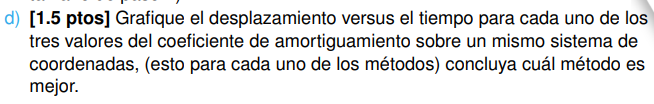

%escribir aquí la solución


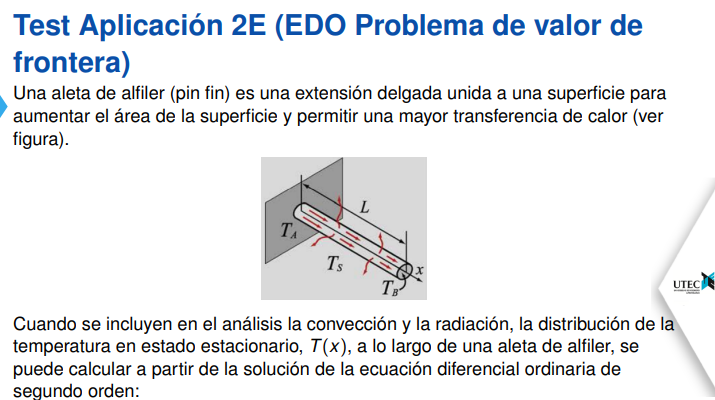

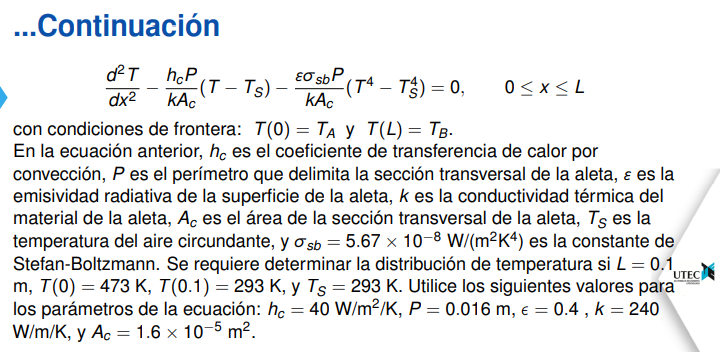

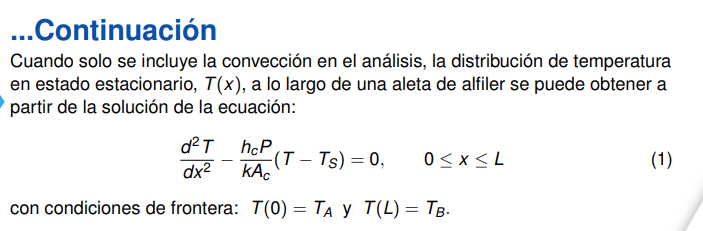

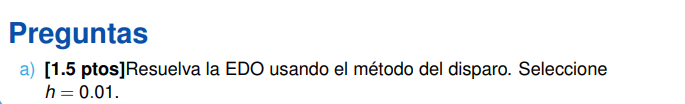

%escribir aquí la solución


%escribir aquí la solución


function z = rk2(f, a, b, y0, h)
    t = [a:h:b];
    z = [t(1) y0(1) y0(2)];
    n = length(t);
    for k = 1:n-1
        k1 = f(t(k), y0);
        k2 = f(t(k+1), y0+h*k1);
        y1 = y0 + (h/2) * (k1+k2);   
        z = [z; t(k+1) y1(1) y1(2)];
        y0 = y1;
    end
end